# Asesoria

### Metodos Numericos

#### 2022-2S : 04/11/2022

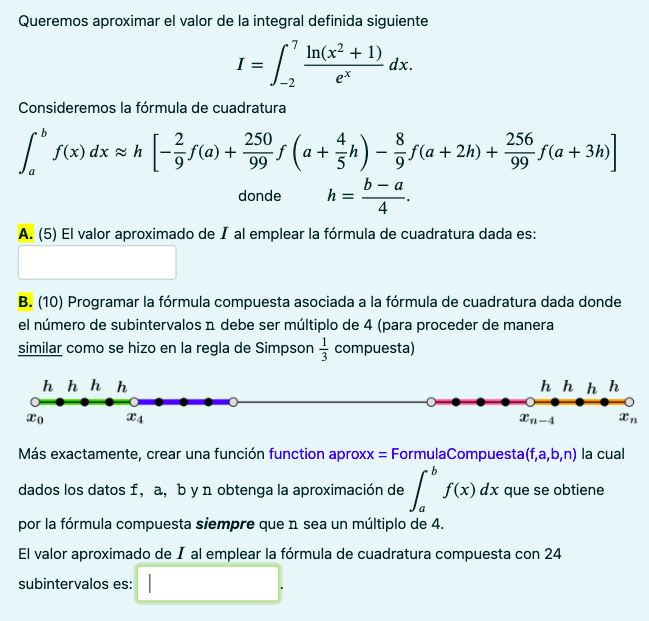

clear
format long

f = @(x) log(x.^2 + 1) .* exp(-x);

Isimple = reglaSimple(f, -2, 7)
Icompuesta = reglaCompuesta1(f, -2, 7, 24)

#### Duda Jhon. Manejo de digitos y cifras

clear

Isimple =   -5.840103010584326


syms f(x)

Icompuesta =    7.003050802615951



f(x) = exp(x);

value = f(20)           % Valor que quiero conocer
eval(value)             % Evaluación del valor
vpa(value, 10)          % Valor númerico simbolico
round(eval(value), 0)   % Valor redondeado

#### Duda Alexander. Cuadratura

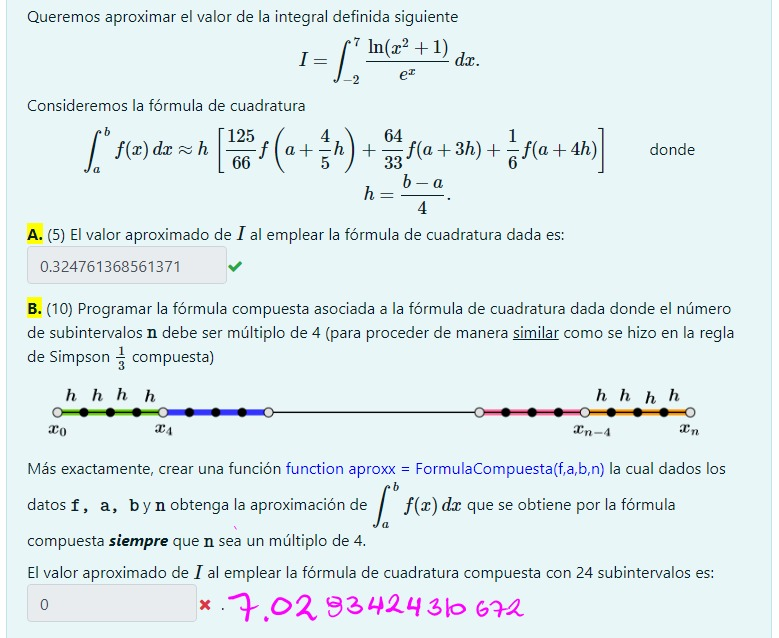

clear

$$value = {\mathrm{e}}^{20}$$

format long

ans =      4.851651954097903e+08


$$ans = 485165195.4$$

f = @(x) log(x.^2 + 1) .* exp(-x);          % Definimos la función

ans =    485165195



Isimple = reglaSimple(f, -2, 7)             % Regla simple
Icompuesta = reglaCompuestaR(f, -2, 7, 24)  % Regla compuesta Recursiva
Icompuesta = reglaCompuestaI(f, -2, 7, 24)  % Regla compuesta Iterativa
ICompartida = cuad1(f, -2, 7, 24)           % Regla compartida Arreglada

clear
syms f(t, y)


Isimple =    0.324761368561371


f(t, y) = 1 + y / t;

Icompuesta =    7.028342431067219


df(t, y) = diff(f, t) + diff(f, y) * f;

Icompuesta =    7.028342431067218


d2f(t, y) = diff(df, t) + diff(df, y) * f;

ICompartida =    7.028342431067218


d3f(t, y) = diff(d2f, t) + diff(d2f, y) * f;

df(t, y) = [f(t, y), df(t, y), d2f(t, y), d3f(t, y)];

df = matlabFunction(df);

a = 1; b = 4; ya = 3; M = 30;

T4 = taylor(df, a, b, ya, M)
T4(T4(:, 1) == 3.6, :)

#### Dudas Juan Pablo

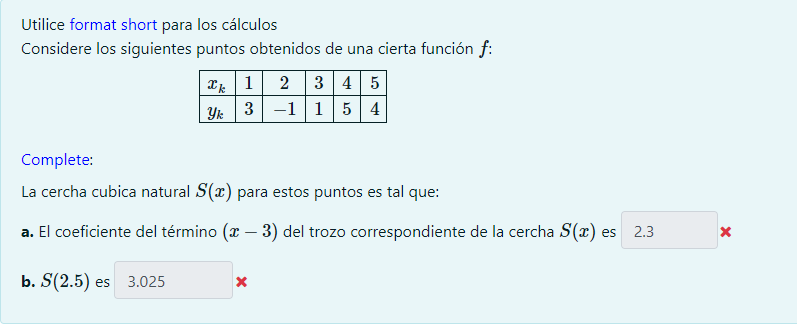

clear

X = 1:5;                            % Definimos el vector X
Y = [3 -1 1 5 4];                   % Definimos el vector Y


T4 =     1.0000    3.0000
    1.1000    3.4048
    1.2000    3.8188
    1.3000    4.2411
    1.4000    4.6711
    1.5000    5.1082
    1.6000    5.5520
    1.7000    6.0021
    1.8000    6.4580
    1.9000    6.9195


coef = csnatural(X, Y);             % Hallamos la matriz de coeficientes

ans =     3.6000   15.4114



coef(3, 3)                          % Busco el 3er nodo 3er coef (Lineal)
P2 = @(x) polyval(coef(2,:), x);    % Definio el spline del nodo 2
P2(2.5)                             % Evaluo en el valor que busco

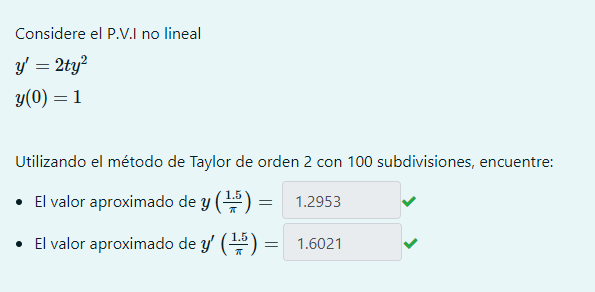

% Para evitar redundancias por fuera del cuaderno, voy a utilizar SYMS
clear
syms f(t, y)

f(t, y) = 2*t*y^2;                              % Definimos la función
df(t, y) = diff(f, t) + diff(f, y)*f(t, y);     % Hallamos la derivada

df(t, y) = [f(t, y), df(t, y), 0, 0];           % Vectorizamos
df = matlabFunction(df);                        % Procesamos la función

values = taylor(df, 0, 1.5/pi, 1, 100);         % Aplicamos el método
t = values(:, 1); y = values(:, 2);             % Separamos en valores de t & y

y(end)                                          % Valor de y(t = 1.5/pi)

dy = 2*t(end)*y(end)^2                          % Valor de la derivada

%function I = reglaSimple(f, a, b)
% input     - f  Función creada con @
%           - a y b Limites del intervalo
% output    - I Valor númerico de la regla de integración

h = (b - a) / 4;

% Variables
x0 = a;

ans = 1.2953

x1 = a + 4/5*h;
x2 = a + 2*h;

dy = 1.6021

x3 = a + 3*h;

I = h * (-2/9 *feval(f, x0) + 250/99 * feval(f, x1) - 8/9 * feval(f, x2) + 256/99 * feval(f, x3));

%end

%function I = reglaCompuesta1(f, a, b, M)
% input     - f  Función creada con @
%           - a y b Limites del intervalo
%           - M es el número de subintervalos
% output    - I Valor númerico de la regla de integración

if not(mod(M, 4) == 0)
    error('Problema con la definición de M, debe ser multiplo de 4')
end

h = (b - a) / M;

I = 0;

for k = 1:M/4
    inicio = a + 4*(k - 1)*h;   % Inicio de Iteración
    fin = a + 4*k*h;            % Fin de Iteración

    I = I + reglaSimple(f, inicio, fin);
end

%end

#### Funciones para la Duda de Alexander

function I = reglaSimple(f, a, b)
% input     - f  Función creada con @
%           - a y b Limites del intervalo
% output    - I Valor númerico de la regla de integración

h = (b - a) / 4;

% Variables
x1 = a + 4/5*h;
x2 = a + 3*h;
x3 = a + 4*h;

I = h * (125/66 *feval(f, x1) + 64/33 * feval(f, x2) + 1/6 * feval(f, x3));

end

function I = reglaCompuestaR(f, a, b, M)
% input     - f  Función creada con @
%           - a y b Limites del intervalo
%           - M es el número de subintervalos
% output    - I Valor númerico de la regla de integración

if not(mod(M, 4) == 0)
    error('Problema con la definición de M, debe ser multiplo de 4')
end

h = (b - a) / M;

I = 0;

for k = 1:M/4
    inicio = a + 4*(k - 1)*h;   % Inicio de Iteración
    fin = a + 4*k*h;            % Fin de Iteración

    I = I + reglaSimple(f, inicio, fin);
end

end

function I = reglaCompuestaI(f, a, b, M)
% input     - f  Función creada con @
%           - a y b Limites del intervalo
%           - M es el número de subintervalos
% output    - I Valor númerico de la regla de integración

if not(mod(M, 4) == 0)
    error('Problema con la definición de M, debe ser multiplo de 4')
end

h = (b - a) / M;
s1 = 0; s2 = 0; s3 = 0;

for k = 1:M/4
    increment = 4*(k - 1)*h;

    x1 = a + 4/5*h + increment;
    x2 = a + 3*h + increment;
    x3 = a + 4*h + increment;

    s1 = s1 + feval(f, x1);
    s2 = s2 + feval(f, x2);
    s3 = s3 + feval(f, x3);

end

I = h * (125/66 *s1 + 64/33 * s2 + 1/6 * s3);
end